# Project 7 (Drone Battery and Flight Time)

%{
t
   originally from ES115 Engineering Computer Applications, Module 2
   project bank, project 16
Author: Tori Testa
Version: 1.0
Date: 2026-04-04
Purpose:
   -
Input:
   -
Output:
   -
Engineering Algorithems:
   -
MATLAB tools/functions:
   -
Reflection
   -
%}

% battery energy depletion over time
t = 0:1:5000;
% Define power consumption levels for different flight modes
EnrgFC = 50000; % how much energy (J) the drone has when fully charged
hoverP = 100;
cruiseP = 200;
ascentP = 300;
E = zeros(size(t)) % defines E as energy over time

E =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


E(1) = EnrgFC;
mode = strings(size(t));
for i = 2:length(t)
    
    if t(i) < 300
        P = ascentP;
        mode(i) = "Ascent";
        
    elseif t(i) < 2000
        P = cruiseP;
        mode(i) = "Cruise";
        
    else
        P = hoverP;
        mode(i) = "Hover";
    end
     dt = t(i) - t(i-1);
    E(i) = E(i-1) - P * dt;
    if E(i) <= 0  % this part makes it stop when the battery is depleted
        E(i) = 0;
        t = t(1:i);
        E = E(1:i);
        mode = mode(1:i);
        break
    end
end


% total flight time before battery depletion
tFlight = t(end);
fprintf('Total flight time before battery depletion: %g', tFlight)

Total flight time before battery depletion: 167

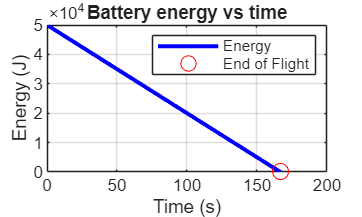

% plot showing energy depletion and end of flight condition
plot(t, E,'b-', 'LineWidth',2)
title('Battery energy vs time')
xlabel('Time (s)')
ylabel('Energy (J)')
grid on
hold on
plot(t(end), E(end), 'ro', 'MarkerSize', 8, 'DisplayName', 'End of Flight')
legend('Energy','End of Flight')
hold off

% interpretation of how flight mode affects endurance